# Reading multiple sur files

This guide explains how multiple sur files from different points in time during the model simulation can be read in to Matlab easily

## Producing a run with multiple outputs

First, we'll ensure we have a run with multiple outputs.

run = project.solidsRuns.new

run =   Solids with properties:

                     modelFile: [1×1 NewDepomod.PropertiesFile]
        physicalPropertiesFile: [1×1 NewDepomod.PropertiesFile]
             configurationFile: [1×1 NewDepomod.PropertiesFile]
                   runtimeFile: [1×1 NewDepomod.PropertiesFile]
                    inputsFile: [1×1 NewDepomod.InputsPropertiesFile]
           iterationInputsFile: [0×0 NewDepomod.InputsPropertiesFile]
        exportedTimeSeriesFile: [0×0 NewDepomod.TimeSeriesFile]
    consolidatedTimeSeriesFile: [0×0 NewDepomod.TimeSeriesFile]
                     solidsSur: [0×0 Depomod.Sur.Solids]
                     carbonSur: [0×0 Depomod.Sur.Solids]
                         label: '2'
            iterationRunNumber: []
                 modelFileName: 'bay_of_fish-2-NONE.depomodmodelproperties'
                          tide: 'N'
                   resultsPath: 'C:\newdepomod_projects\bay_of_fish\

run.setRunDurationDays(30);
run.clearOutputTimes;
run.setDailyOutputTimes;
run.execute;

Starting simulation...
Command: "C:\Program Files\depomodruntimecontainer\bin\depomodruntimecontainer" --modelRunTimeFile "C:\newdepomod_projects\bay_of_fish\depomod\models\bay_of_fish-2-NONE.depomodruntimeproperties" --nosplash --singleRunOnly --showConsoleOutput --showConsoleProgress
Time: 10-Jun-2019 13:27:29
Elapsed time is 1.044808 seconds.


This produces a short, 30-day run with seabed impact information outputted once per day.

## Reading in multiple sur files

In order to read in multiple files we need the timestamps at whcih they were outputted. These can be retrieved easily using

t = run.outputTimestamps

These are the output times (in seconds) for which we should have sur files. There are 29 of them. We can read all of them in like this:

surs = run.sur('type', 'solids', 'g', 0, 't', t)

Notice that we now have 29 surs held in a cell array. Let's plot 2 of them

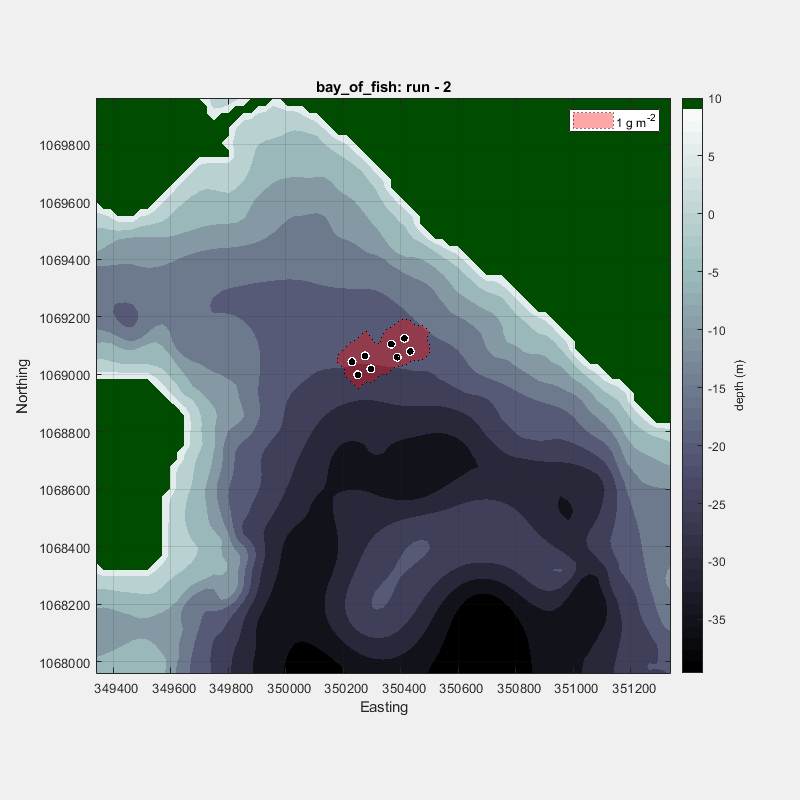

ans =   Figure (20) with properties:

      Number: 20
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties

run.plot('sur', surs{5}, 'levels', [1 250])

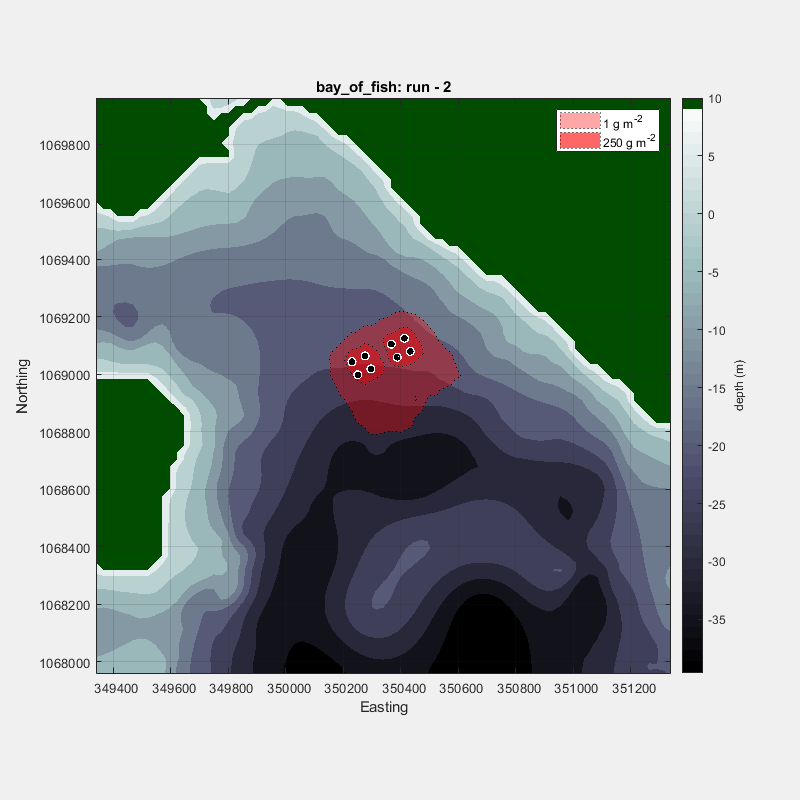

ans =   Figure (21) with properties:

      Number: 21
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties

run.plot('sur', surs{25}, 'levels', [1 250])